## Задание 1

#### 1,1 проверка обекта на сократимость

syms t s;

b = s - 1;
a = 0.5*s^2 + s -1;

W =b/a

$$W = \frac{s-1}{\frac{s^{2}}{2}+s-1}$$

double(solve(a ==0)), double(solve(b == 0))

ans =    -2.7321
    0.7321


ans = 1

нули системы и полюча не сокращаются

#### 1.2 формирование модели задающих и воздействующих воздействий в виде вход-состояние-выход


g(t) = 6*cos(5*t+3);
f(t) = 8*cos(5*t+2);

z_1(t) = g(t) 

$$z\_1(t) = 6\,\cos\left(5\,t+3\right)$$

z_1_dot(t) = diff(z_1); z_2(t) = z_1_dot

$$z\_2(t) = -30\,\sin\left(5\,t+3\right)$$

z_2_dot(t) = diff(z_2); z_3(t) = z_2_dot

$$z\_3(t) = -150\,\cos\left(5\,t+3\right)$$

    z_2_dot = k * z_1 выразим

k = z_2_dot/z_1

$$k(t) = -25$$

Выразим матрицу E_g и Г

E_g = double([z_1(0); z_2(0)]), G = double([0 1; k 0])

E_g =    -5.9400
   -4.2336


G =      0     1
   -25     0


Найдем для f(t)

z_1(t) = f(t) 

$$z\_1(t) = 8\,\cos\left(5\,t+2\right)$$

z_1_dot(t) = diff(z_1); z_2(t) = z_1_dot

$$z\_2(t) = -40\,\sin\left(5\,t+2\right)$$

z_2_dot(t) = diff(z_2); z_3(t) = z_2_dot

$$z\_3(t) = -200\,\cos\left(5\,t+2\right)$$

    z_2_dot = k * z_1 выразим

k = z_2_dot/z_1

$$k(t) = -25$$

E_12 = double([z_1(0); z_2(0)]), G = double([0 1; k 0])

E_12 =    -3.3292
  -36.3719


G =      0     1
   -25     0


**подытожим:**

G , H_1 = [1 0], H_2 = H_1/2, H_g = [1 0], E_12, E_g

G =      0     1
   -25     0


H_1 =      1     0


H_2 =     0.5000         0


H_g =      1     0


E_12 =    -3.3292
  -36.3719


E_g =    -5.9400
   -4.2336


% clear; 

t_p = 0.2; sigma = 16; syms s ; 

#### **1.3 Определение порядка желаемого характеристического полинома по формуле**

w = 9.2/t_p

w = 46.0000

n = 2*2 + 2 - 1

n = 5

Из-за того что перерегулированние нулевое, используем полином Ньютона                      

a(s) = s^5 + 5*w*s^4 + 10*w^2*s^3 + 10*w^3*s^2 + 5*w^4*s + w^5 ,aa = sym2poly(a(s))

$$a(s) = s^{5}+230\,s^{4}+21160\,s^{3}+\frac{2090274683617279\,s^{2}}{2147483648}+\frac{1502384928849919\,s}{67108864}+\frac{6910970672709627}{33554432}$$

aa = 	1.0e+08 *

    0.0000    0.0000    0.0002    0.0097    0.2239    2.0596


#### 1.4 **Расчет параметров передаточной функции регулятора в соответствии с соотношениями**

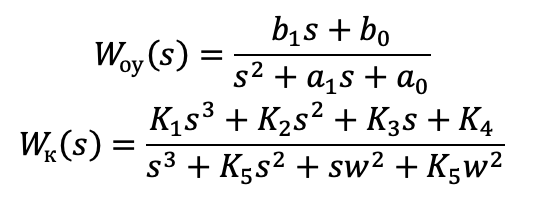

Приравняем знаменатель передаточной функции замкнутой системы к желаемому характеристическому полиному

b1=1;
b0=-1;
a1=1;
a0=0.5;
w = 5;
w0 = w; 
w02=w0^2;

H1 = H_1; H2 = H_2; Hg = H_g;
 
syms k1 k2 k3 k4 k5;
eqn1=k5+a1+k1*b1==5*w0^1;
eqn2=w02+a0+k5*a1+k1*b0+k2*b1==10*w0^2;
eqn3=k5*w02+a1*w02+k5*a0+k2*b0+k3*b1==10*w0^3;
eqn4=a0*w02+k3*b0+k4*b1+k5*a1*w02==5*w0^4;
eqn5=k5*a0*w02+k4*b0==1*w0^5;
syms s
sol=solve([eqn1; eqn2; eqn3; eqn4; eqn5], [k1, k2, k3, k4, k5]);
K1=double(sol.k1);
K2=double(sol.k2);
K3=double(sol.k3);
K4=double(sol.k4);
K5=double(sol.k5) ;
Roots1 = eig(tf([K1*b1 K1*b0+K2*b1 K2*b0+K2*b0+K3*b1 K3*b0+K4*b1 K4*b0],[1 K5+a1+K1*b1 w02+a0+K5*a1+K1*b0+K2*b1 K5*w02+a1*w02+K5*a0+K2*b0+K3*b1 a0*w02+K3*b0+K4*b1+K5*a1*w02 K4*b0+K5*a0*w02]));
Roots2 = double(solve(s^5+5*w0*s^4+10*w0^2*s^3+10*w0^3*s^2+5*w0^4*s+w0^5==0));
K1, K2, K3, K4, K5, Roots1, Roots2

K1 = -94.6308

K2 = 11.2385

K3 = -1.7888e+03

K4 = -1.6421e+03

K5 = 118.6308

Roots1 =   -5.0048 + 0.0035i
  -5.0048 - 0.0035i
  -4.9982 + 0.0057i
  -4.9982 - 0.0057i
  -4.9940 + 0.0000i


Roots2 =     -5
    -5
    -5
    -5
    -5


#### 1.5 Провверочный расчет **характеристического полинома замкнутой системы**

Полюса передаточной функции:

Roots1

Roots1 =   -5.0048 + 0.0035i
  -5.0048 - 0.0035i
  -4.9982 + 0.0057i
  -4.9982 - 0.0057i
  -4.9940 + 0.0000i


Корни желаемого характеристического полинома:

Roots2

Roots2 =     -5
    -5
    -5
    -5
    -5


Корни совпали с полюсами, значит коэффициенты были посчитаны верно

#### **1.6 Моделирование системы управления**

Модель наблюдения

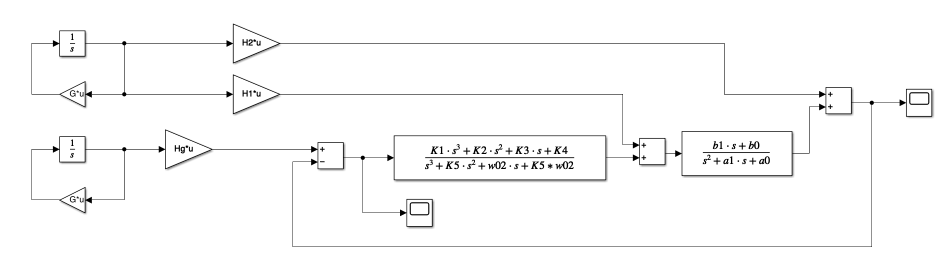

График выхода

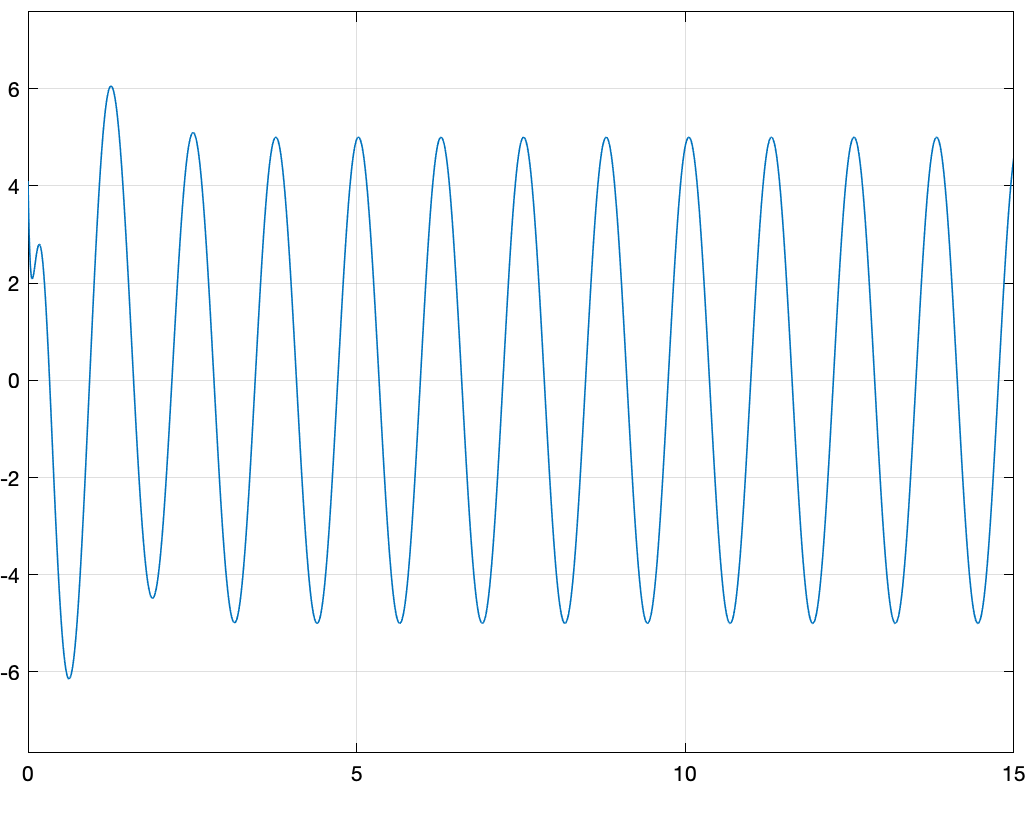

график ошибки

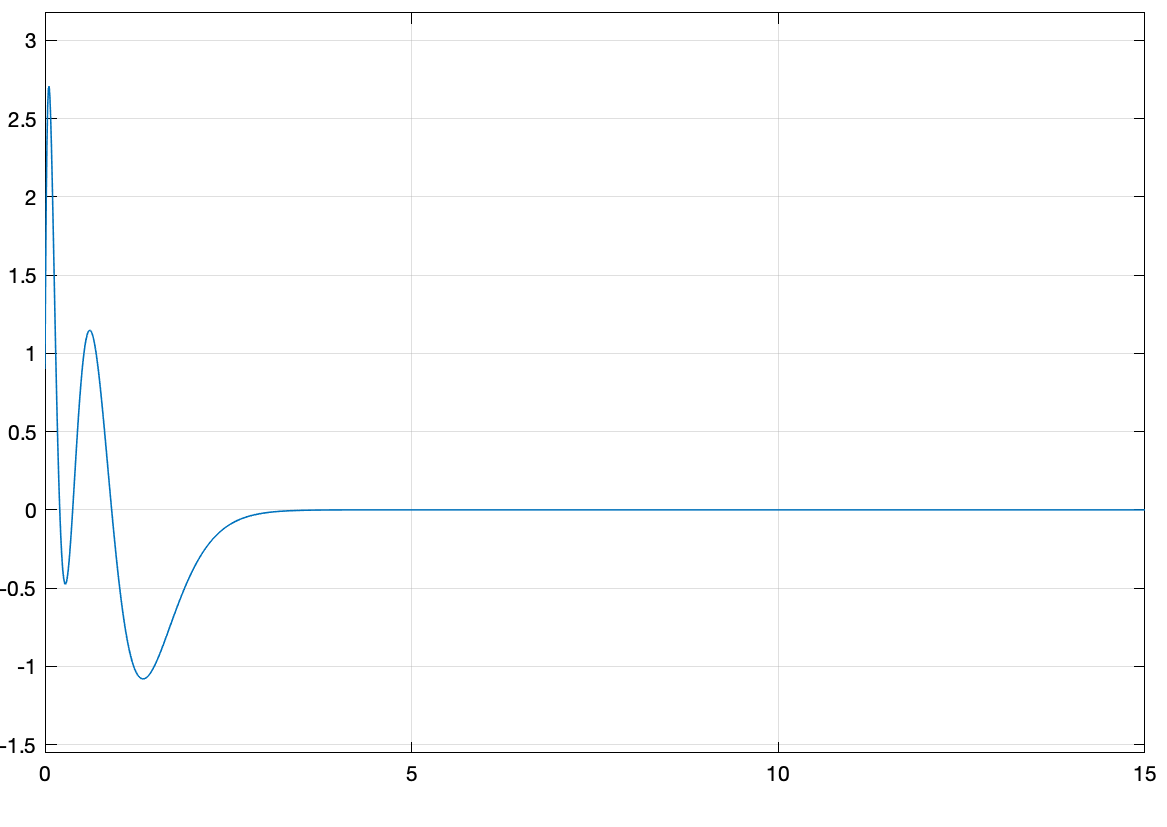

ошибка системы сходится в ноль  -> система решена верно 

### **2 Управление объектом в виде модели вход-состояние-выход (астатический регулятор).**

clear all;
syms t;
D = 6;
A = [2 6; 1 0];
B = [4;1];
C = [2 0];

Bf = [1;3];
tp = 0.2; sigma = 16;
g(t) = 2.8*t;
f1 = 9; f2 = 8;

#### **2.1 Проверка объекта управления на свойства полной управляемости и наблюдаемости**

 rank([B A*B]) % матрица управляема

ans = 2

rank([C; C*A]) % rank = 2, матрица полностью наблюдаема

ans = 2

**2.2 Формирование внешних воздействий**

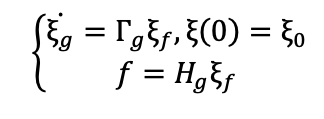

z_1(t) = g(t) 

$$z\_1(t) = \frac{14\,t}{5}$$

z_1_dot(t) = diff(z_1); z_2(t) = z_1_dot

$$z\_2(t) = \frac{14}{5}$$

z_2_dot(t) = diff(z_2); z_3(t) = z_2_dot

$$z\_3(t) = 0$$

    z_2_dot = k * z_1 выразим

k = z_2_dot/z_1

$$k(t) = 0$$

Выразим матрицу E_g и Г

E_g = double([z_1(0); z_2(0)]), T2 = double([0 1; k 0]), Hg = [1 0]

E_g =          0
    2.8000


T2 =      0     1
     0     0


Hg =      1     0


#### **2.3 Построение встроенной модели вида**

По условию Г=0, тогда из условия полной наблюдаемости пары (Г, G) можно выбрать G=1;

#### 2.4 **Конструирование эталонной модели на основе требуемых показателей качества**

w = 6.3/tp, G = [0 0 -w^3; 1 0 -3*w^2; 0 1 -3*w], H = [0 0 1]

w = 31.5000

G = 	1.0e+04 *

         0         0   -3.1256
    0.0001         0   -0.2977
         0    0.0001   -0.0094


H =      0     0     1


#### **2.5 Нахождение матрицы и расширенной матрицы линейных стационарных обратных связей из уравнений**

syms s;
T2_1=[0 1; 0 0];
G=1;
w2=w;
 
T2_=[0 0 -w2^3; 1 0 -3*w2^2; 0 1 -3*w2];
H_=[0 0 1];
A_=[0 -G*C; zeros(2, 1) A];
B_=[-G*D; B];
G_=[G; zeros(2, 1)];
Bf_=[0; Bf];
 
M_=sylvester(-A_, T2_, B_*H_);
K_=-H_*inv(M_); M_,K_

M_ =     0.0002    0.0002    0.0006
   -0.0001   -0.0003   -0.0012
   -0.0000   -0.0001   -0.0003


K_ = 	1.0e+04 *

    0.1302    0.9024   -2.8185


Ke = K_(1), Kx = [K_(2) K_(3)]

Ke = 1.3023e+03

Kx = 	1.0e+04 *

    0.9024   -2.8185


#### **2.6 Вычисление матрицы замкнутой системы с последующим вычислением корней её характеристического полинома и сравнение их с корнями требуемого характеристического полинома**

eig(A_ - B_ * K_)

ans =  -31.4939 + 0.0105i
 -31.4939 - 0.0105i
 -31.5121 + 0.0000i


double(solve(s^3 + 3*w2*s^2 + 3*w2^2*2 + w2^3 == 0))

ans =    1.9235 -19.3558i
   1.9235 +19.3558i
 -98.3471 + 0.0000i


#### 2.7 Моделирование

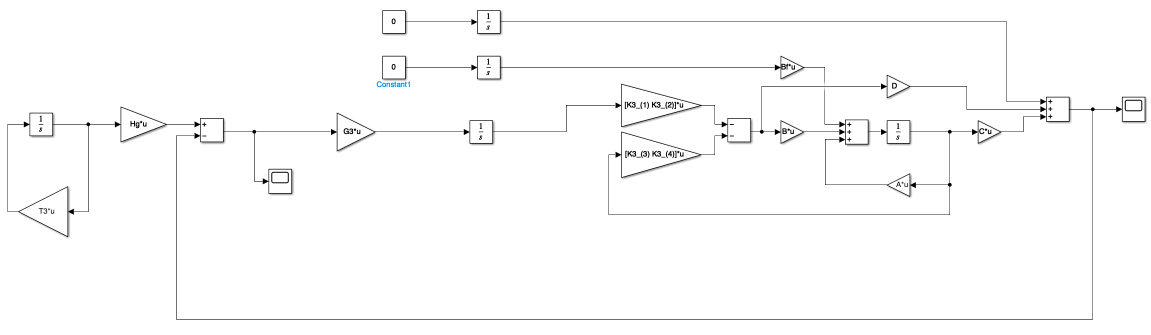

 график ошибки

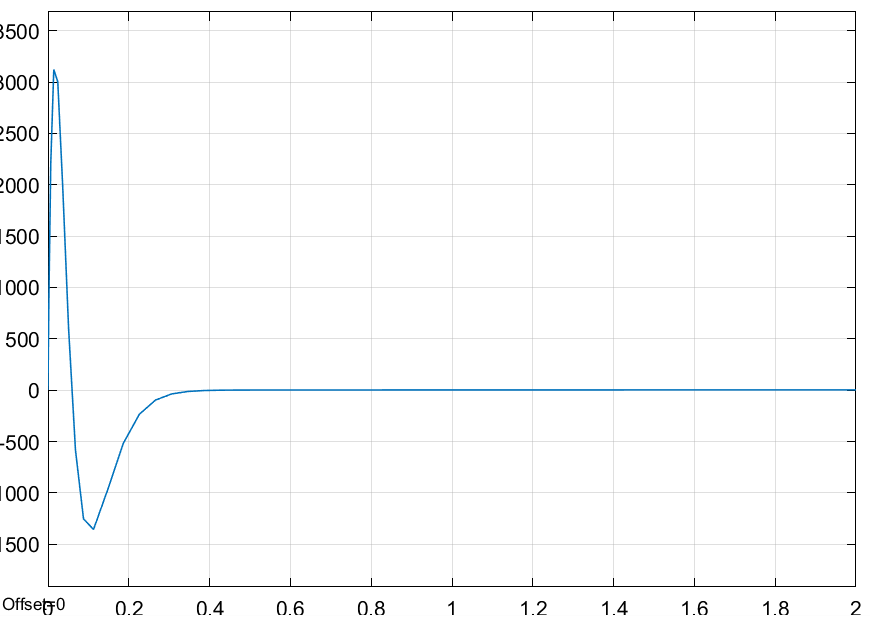

#### **3. Управление объектом в виде модели вход-состояние-выход**

#### **(метод встроенной модели)**

#### 3.1 **Формирование моделей внешних воздействий в виде вход-состояние выход**

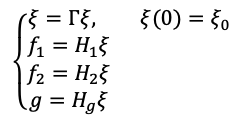

#### **3.2 Построение встроенной модели вида**

T3 = [0 1; -25 0]; % взяята из начала отчета
G3 = [1;1];

#### **3.3 Конструирование эталонной модели на основе требуемых показателей качества**

w3 = 7.8/tp, T3_=[0 0 0 -w3^4; 1 0 0 -4*w3^3; 0 1 0 -6*w3^2; 0 0 1 -4*w3], H3_=[0 0 0 1]

w3 = 39

T3_ =            0           0           0    -2313441
           1           0           0     -237276
           0           1           0       -9126
           0           0           1        -156


H3_ =      0     0     0     1


A3_=[T3 -G3*C; zeros(2,2) A];
B3_=[-G3*D; B];
G3_=[G3; zeros(2, 1)];
Bf3_=[zeros(2, 1); Bf];

M3_=sylvester(-A3_, T3_, B3_*H3_)

M3_ = 	1.0e+-3 *

    0.0017    0.0101   -0.0316   -0.2117
    0.0076   -0.0400   -0.2433    0.8226
   -0.0012   -0.0042   -0.0158   -0.0567
   -0.0003   -0.0012   -0.0042   -0.0158


invM3_=inv(M3_);
K3_=-H3_*invM3_

K3_ = 	1.0e+05 *

    0.0150   -0.0044   -0.3376    1.4150


#### 3.5 **Вычисление матрицы замкнутой системы с последующим вычислением корней её характеристического полинома и сравнение их с корнями требуемого характеристического полинома**

eig(A3_-B3_*K3_)

ans =  -39.1704 + 0.0000i
 -38.9997 + 0.1701i
 -38.9997 - 0.1701i
 -38.8302 + 0.0000i


 собственные числа замкнутой системы удовлетворяют желаемым корням.

#### 3.6 **Моделирование системы управления**

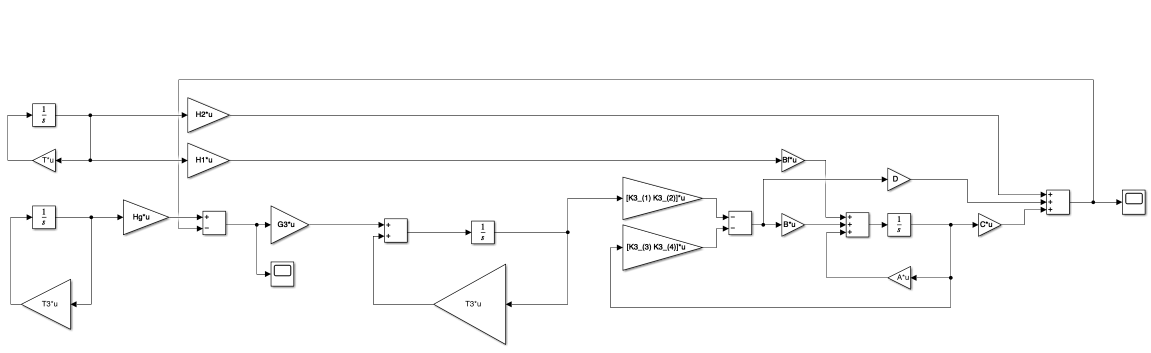

график выхода

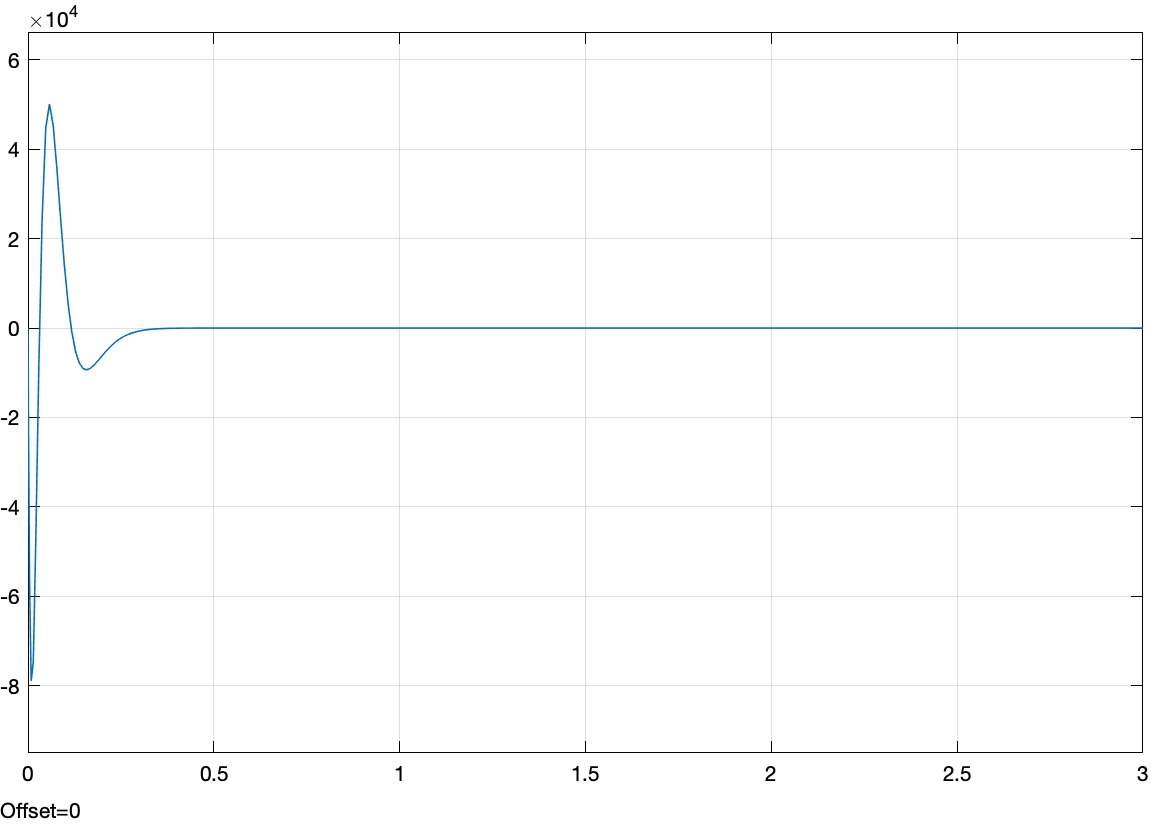

График ошибки

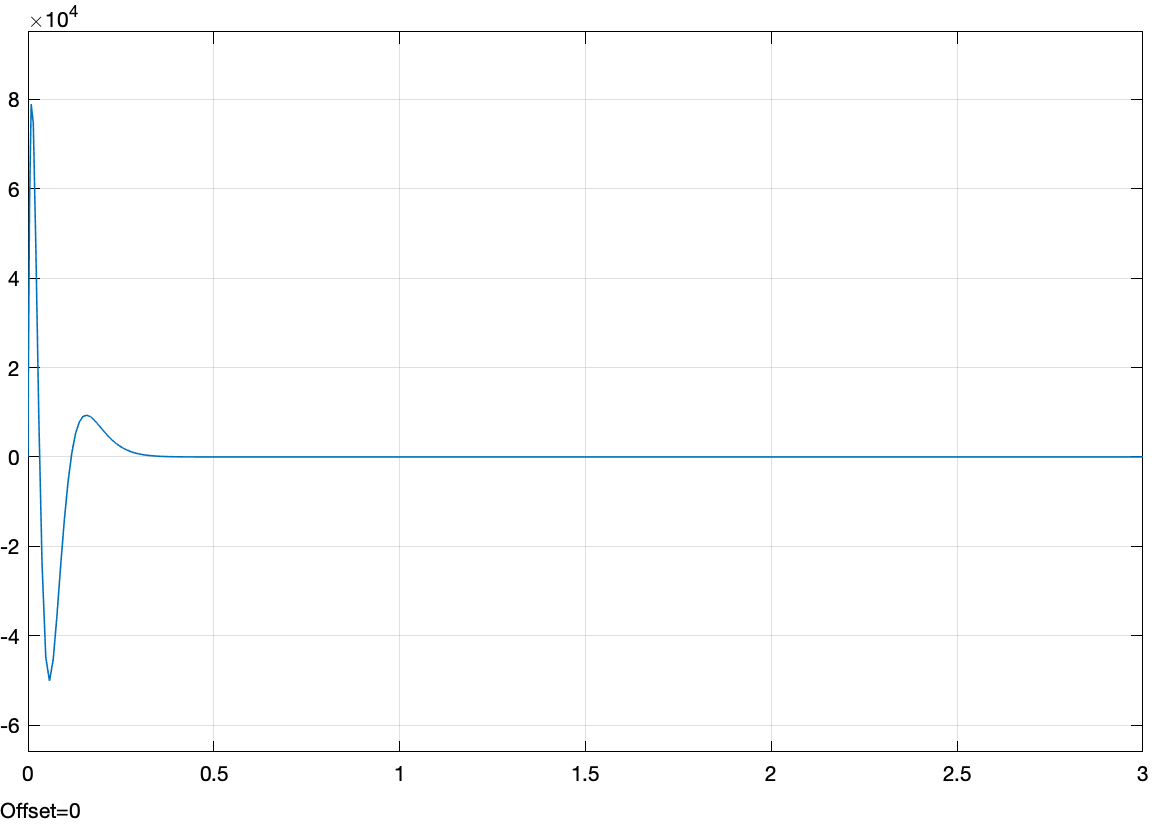

По графикам можно увидеть, что ощибка сведена к нулю

## ВЫВОД

в результате выполнения данной лабораторной работы было освоено управление линейными объектами с помощь метода внутренней (встроенной) модели. Рассчитаны параметры и смоделированы системы слежения и компенсации. Построены графики выходных переменных, вектора состояния ОУ, генераторы возмущающего и внешнего воздействия.